# This routine is intended at analyzing Cp data acquired with the shared PPMS in McCullough 015

## To do: check error bars

For T data, compare the dispersion of the measured points with the percent temperature increase 

For Cp values, compare the dispersion of the measured points with the SampHCErrmJmoleK field

# Cp vs T

## Import data

Data = importCpSharedPPMS_('2018-09-07_10V-TmAsO4-LS5350-HC180907_CpvsT.dat');

## Assign variable names and get rid of NaN rows

H=[Data.FieldOersted];
T=[Data.SampleTempKelvin];
Cp=[Data.SampHCmJmoleK];
dT = [Data.TempRiseKelvin];

whichPoints = isfinite(T) & isfinite(Cp) & isfinite(dT);
H=H(whichPoints);
T=T(whichPoints);
Cp=Cp(whichPoints);
dT = dT(whichPoints);
temprise = dT./T;
septemprise = unique(round(temprise,2))

septemprise =     0.0100
    0.0200
    0.0300


## Filter data according to value of magnetic field

uh = unique(round(H,-1))

uh =            0
        4000
        8000
       12000
       14000
       15000
       15500
       16000
       20000


filterH = false(length(H),length(uh));
for i=1:length(uh)
    filterH(:,i) = abs(H-uh(i))<10;

    hsd(i).H = H(filterH(:,i));
    hsd(i).T = T(filterH(:,i));
    hsd(i).Cp = Cp(filterH(:,i));
    hsd(i).temprise = temprise(filterH(:,i));
    
    [hsd(i).T,wo] = sort(hsd(i).T);
    hsd(i).H = hsd(i).H(wo);
    hsd(i).Cp = hsd(i).Cp(wo);
    hsd(i).temprise = hsd(i).temprise(wo);
end

## Plot the full dataset

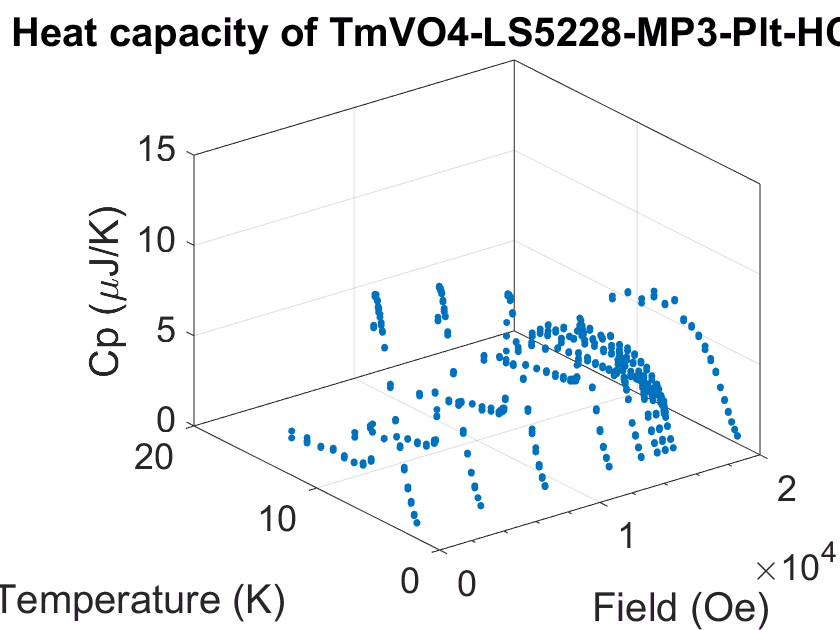

figure
% hmax=5500;
scatter3(H,T,Cp,'.')
% xlim([0 hmax])
% ylim([0 3])
% xlabel('Field (Oe)')
xlabel('Field (Oe)')
ylabel('Temperature (K)')
zlabel('Cp (\muJ/K)')
title('Heat capacity of TmVO4-LS5228-MP3-Plt-HC1803')

## Plot field separated data

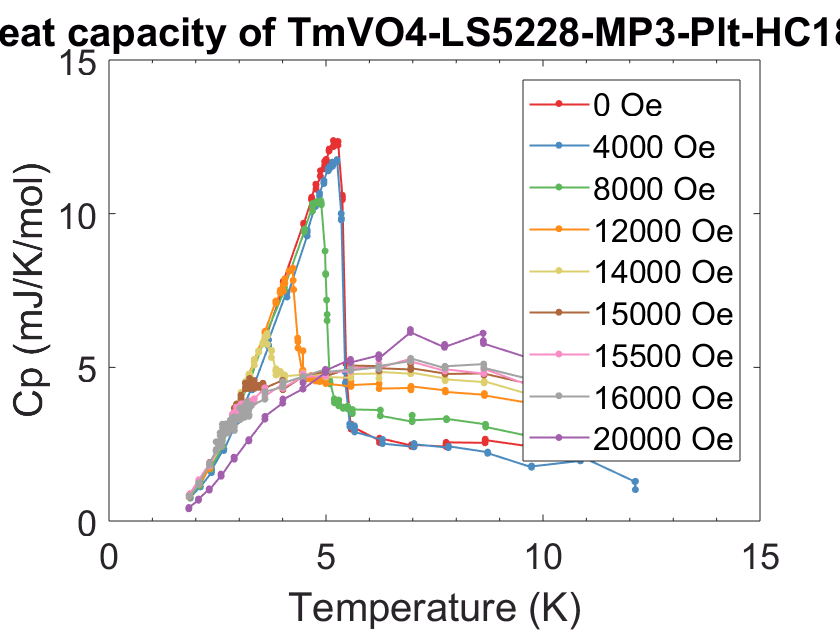

clr = linspecer(length(uh)); 
figure
for k=1:length(uh)
    plot(hsd(k).T,hsd(k).Cp,...
        '.-','markers',12,'color',clr(k,:),'Displayname',num2str(uh(k)', '%d Oe'))
    hold on
end
xlabel('Temperature (K)')
ylabel('Cp (mJ/K/mol)')
title('Heat capacity of TmVO4-LS5228-MP3-Plt-HC1803')
legend('show')

## Smooth data

This is a very bad idea because it smoothes data along the temperature axis; the resulting dataset is therefore not physical

% sgm = 1;
% figure
% for k=1:length(uh)
%     hsd(k).Cpg = gConvolve(hsd(k).Cp,sgm);
%     plot(hsd(k).T,hsd(k).Cpg,...
%         '.-','markers',12,'color',clr(k,:),'Displayname',num2str(uh(k)', '%d Oe'))
%     hold on
% end

## Compute average of data points taken within 4.5mK of one another

+-5mK is the empirical maximal dispersion of data points taken consecutively at a given temperature

for k=1:length(uh)
    Tsm = zeros(floor(length(hsd(k).T)/3),1);
    Tsd = zeros(floor(length(hsd(k).T)/3),1);
    Cpm = zeros(floor(length(hsd(k).T)/3),1);
    Cpd = zeros(floor(length(hsd(k).T)/3),1);
    for i = 2:3:length(hsd(k).T)
        ind = [i];
        for j = i-1:i+3
            if abs(hsd(k).T(j)-hsd(k).T(i))<0.005
                ind = [ind, j];
            end
            if j>= length(hsd(k).T)
                break
            end
        end
        r = (i+1)/3;
        Tsm(r) = mean(hsd(k).T(ind));
        Tsd(r) = std(hsd(k).T(ind));
        Cpm(r) = mean(hsd(k).Cp(ind));
        Cpd(r) = std(hsd(k).Cp(ind));
    end
    hsd(k).Tm = Tsm;
    hsd(k).Td = Tsd;
    hsd(k).Cpm = Cpm;
    hsd(k).Cpd = Cpd;
end

## Plot averaged data

Note: the above average does not distinguish between data measured with different values of temperature rise; there can therefore be a dispersion of data points at the transition for any given field

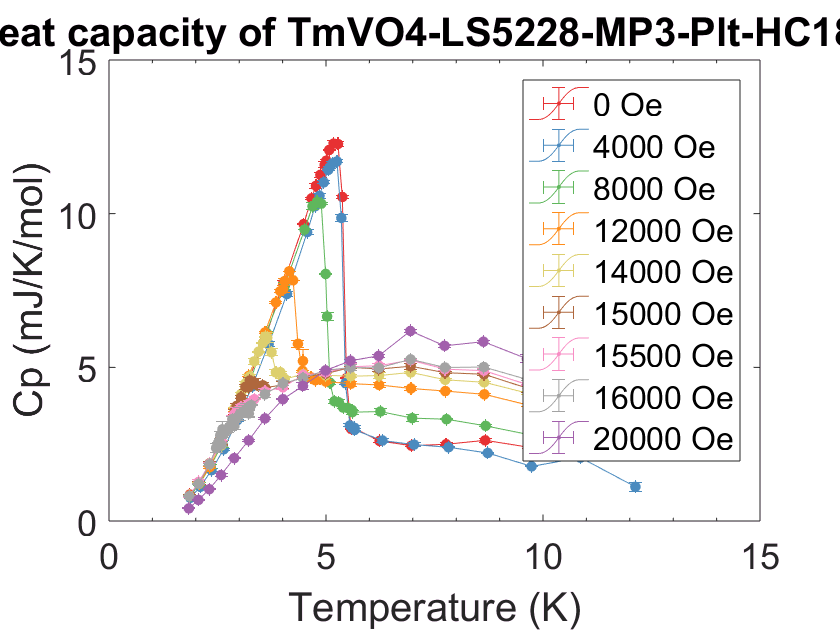

clr = linspecer(length(uh)); 
figure
for k=1:length(uh)
    errorbar(hsd(k).Tm,hsd(k).Cpm,hsd(k).Cpd,hsd(k).Cpd,hsd(k).Td,hsd(k).Td,...
        '.-','markers',18,'color',clr(k,:),'Displayname',num2str(uh(k)', '%d Oe'))
    %error bars need to be specified both positive and negative, hence repetition of Cpd and Td
    hold on
end
xlabel('Temperature (K)')
ylabel('Cp (mJ/K/mol)')
title('Heat capacity of TmVO4-LS5228-MP3-Plt-HC1803')
legend('show')

## Fit 3D surface of raw data >> try to interpolate instead

hmax = max(uh)

hmax = 20000

tmax = max(T)

tmax = 12.1298

tmin = min(T)

tmin = 1.8380

tstep=0.1; 
hstep=1000;% optimal parameter for gridfit
[Hg,Tg] = meshgrid(0:hstep:hmax,tmin:tstep:tmax);% for griddata
Hgl=0:hstep:hmax;% for gridfit
Tgl=tmin:tstep:tmax;% for gridfit
figure
Cpg = gridfit(H,T,Cp,Hgl,Tgl);%try interpolate

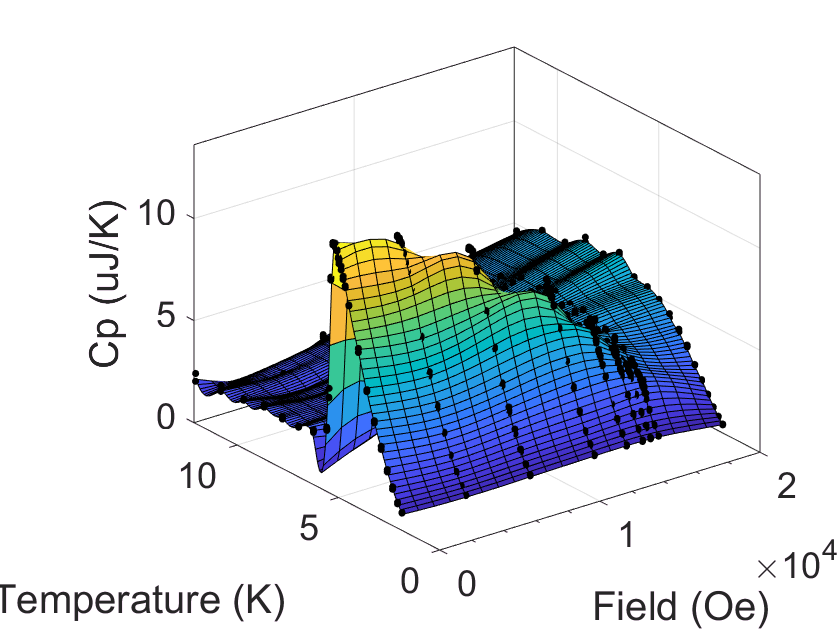

% Cpg = griddata(H,T,Cp,Hg,Tg);% too rough, it only makes connections between points,
% which is not good when the data density is not homogeneous
surf(Hg,Tg,Cpg)
hold on
scatter3(H,T,Cp,100,'.','.k')
ylim([0 tmax])
zlim([0 1.1*max(Cp)])
xlabel('Field (Oe)')
ylabel('Temperature (K)')
zlabel('Cp (uJ/K)')

## Plot the 3D surface color map of the derivative of the surface computed in the previous section

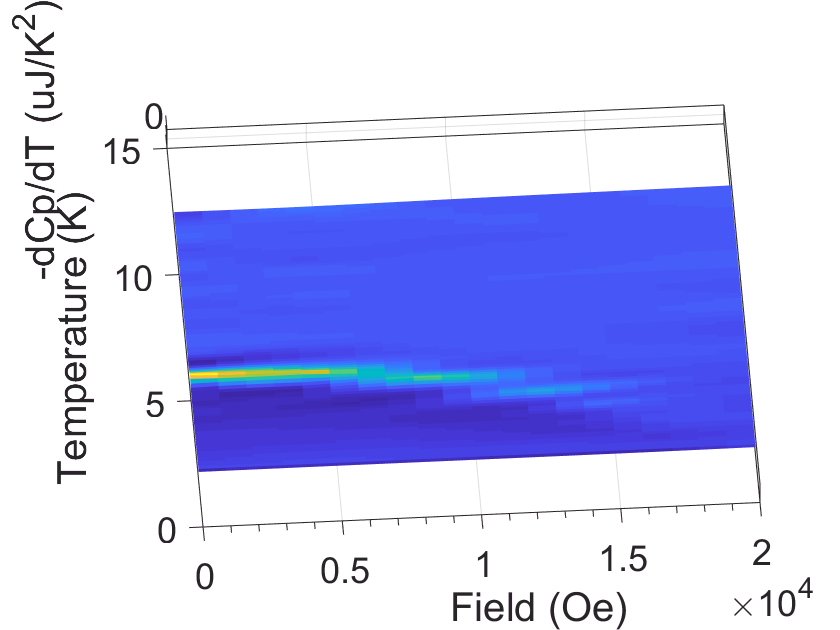

steps = -50:50;
x= tstep*steps;
s=0.05;
d1Gaussian = -exp(-x.^2/(2*s^2)).*x./sqrt(s^6*2*pi);% first derivative of a Gaussian
d2Gaussian = exp(-x.^2/(2*s^2)).*(x.^2 - s^2)/sqrt(s^10*2*pi);% second derivative of a Gaussian

figure
d1Cpg = conv2(Cpg,d1Gaussian','same');
d2Cpg = conv2(Cpg,d2Gaussian','same');
surf(Hg,Tg,-d1Cpg,'EdgeColor','none')
xlabel('Field (Oe)')
ylabel('Temperature (K)')
zlabel('-dCp/dT (uJ/K^2)')

# Cp vs H

## Import data

Data = importCpSharedPPMS_('2018-09-07_10V-TmAsO4-LS5350-HC180907_CpvsH.dat');

Undefined variable "separatedCpData" or class "separatedCpData".

Next steps: 

- plot average data and non-averaged data on same figure (just to compare)

- plot the derivative of dCp/dT as a 3D color plot

- Average Cp vs H and plot it at each temperature

- plot dCp/dH as a 3D color plot

- combine dCp/dT and dCp/dH to get the "full" phase diagram

## Separate data according to the percent temperature increase of the measurement

clear separatedCpData
strtol = 0.004;

for i = 1:length(septemprise)
    wp = abs(temprise-septemprise(i))< strtol;
%     separatedCpData(i).H = H(wp);
    separatedCpData(i).T = T(wp);
    separatedCpData(i).Cp = Cp(wp);
    separatedCpData(i).temprise = temprise(wp);
    
    [separatedCpData(i).T,wo] = sort(separatedCpData(i).T);
%     separatedCpData(i).H = separatedCpData(i).H(wo);
    separatedCpData(i).Cp = separatedCpData(i).Cp(wo);
    separatedCpData(i).temprise = separatedCpData(i).temprise(wo);
end

figure
for i=1:length(septemprise)
    plot(separatedCpData(i).T,separatedCpData(i).Cp,'-+',...
        'Displayname',num2str(100*septemprise(i)', '%.2f %%'))
    hold on
end
xlabel('Temperature (K)')
ylabel('Cp (mJ/K/mol)')
legend('show')
title('Heat capacity of TmVO4-LS5228-MP3-Plt-HC1803')
hold off

## Fitting H-T phase diagram -- 1

tstep=0.05; hstep=500; [Hg,Tg] = meshgrid(0:hstep:hmax,0.365:tstep:3);% for griddata Hgl=0:hstep:hmax;% for gridfit Tgl=0.365:tstep:3;% for gridfit figure Cpg = gridfit(H,T,Cp,Hgl,Tgl); %Cpg = griddata(H,T,Cp,Hg,Tg); surf(Hg,Tg,Cpg) hold on scatter3(H,T,Cp,100,'.','.k') xlabel('Field (Oe)') ylabel('Temperature (K)') zlabel('Cp (uJ/K)')

% %%
% 
% steps = -50:50;
% x= tstep*steps;
% s=0.05;
% d1Gaussian = -exp(-x.^2/(2*s^2)).*x./sqrt(s^6*2*pi);
% d2Gaussian = exp(-x.^2/(2*s^2)).*(x.^2 - s^2)/sqrt(s^10*2*pi);
% 
% figure
% d1Cpg = conv2(Cpg,d1Gaussian','same')
% d2Cpg = conv2(Cpg,d2Gaussian','same')
% surf(Hg,Tg,-d1Cpg,'EdgeColor','none')
% xlabel('Field (Oe)')
% ylabel('Temperature (K)')
% zlabel('-dCp/dT (uJ/K^2)')
% 
%

## Fitting H-T phase diagram -- 2

for i=1:length(septemprise)
    separatedCpData(i).f=fitSpline(separatedCpData(i).T,-separatedCpData(i).Cp);
%Is fitSpline a Matlab function? Cannot find it in the help.
%    separatedCpData(i).d2=differentiate(separatedCpData(i).f,separatedCpData(i).T);
    plot(separatedCpData(i).f,'deriv1')
    hold on
end
legend(legendCell)
xlabel('Temperature (K)')
ylabel('-dCp/dT (uJ/K^2)')
hold off

figure
% n = length(fields);
% C=[]
% for i=0:n-1
%     C=[C; 1-i/n i/n 0];
% end
% set(0,'defaultaxescolororder',C) %red to green
for i=1:length(septemprise)
    separatedCpData(i).f=fitSpline(separatedCpData(i).T,separatedCpData(i).Cp);
    separatedCpData(i).d2=differentiate(separatedCpData(i).f,separatedCpData(i).T);
    scatter3(separatedCpData(i).H,separatedCpData(i).T,-separatedCpData(i).d2,'filled')
    hold on
end
xlim([0 hmax])
ylim([0 3])
xlabel('Field (Oe)')
ylabel('Temperature (K)')
zlabel('-dCp/dT (uJ/K)')
hold off

T2=[];
H2=[];
d2Cp2=[];
for i=1:length(septemprise)
    T2= [T2; separatedCpData(i).T];
    H2=[ H2; separatedCpData(i).H];
    d2Cp2=[d2Cp2; separatedCpData(i).d2];
end

tstep=0.025;
% hmax=8000;
% hstep=500;
% [Hg,Tg] = meshgrid(0:hstep:hmax,0.365:tstep:3);%for griddata
Hgl=0:hstep:hmax;%for gridfit
Tgl=0.365:tstep:3;%for gridfit
figure
d2Cpgf = gridfit(H2,T2,d2Cp2,Hgl,Tgl);
d2Cpg = griddata(H2,T2,d2Cp2,Hg,Tg);
surf(Hg,Tg,-d1Cpg,'EdgeColor','none')
xlabel('Field (Oe)')
ylabel('Temperature (K)')
zlabel('-dCp/dT (uJ/K^3)')
hold on
%scatter3(H2,T2,-d2Cp2,'.k')
xlim([0 hmax])
ylim([0 3])